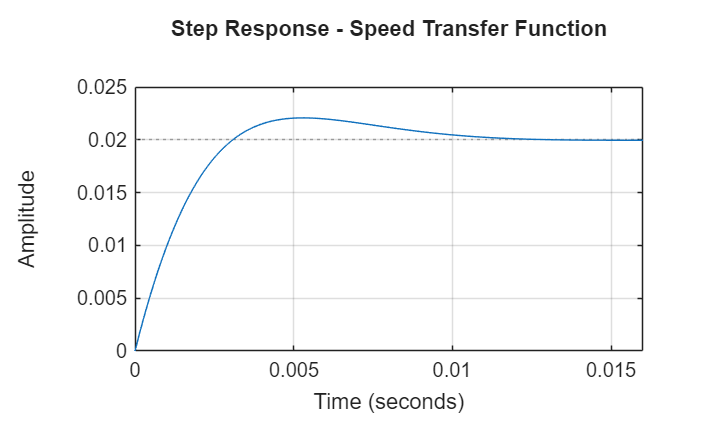


% --- Step Response Characteristics ---
figure;
step(sys_speed);
title('Step Response - Speed Transfer Function');
grid on;


% Get exact characteristics
info = stepinfo(sys_speed);
disp('Step Response Characteristics:');

Step Response Characteristics:


disp(info);

         RiseTime: 0.0022
    TransientTime: 0.0102
     SettlingTime: 0.0102
      SettlingMin: 0.0180
      SettlingMax: 0.0221
        Overshoot: 10.3774
       Undershoot: 0
             Peak: 0.0221
         PeakTime: 0.0053




% DC Gain
K_dc = dcgain(sys_speed);
fprintf('DC Gain: %.4f\n', K_dc);

DC Gain: 0.0200


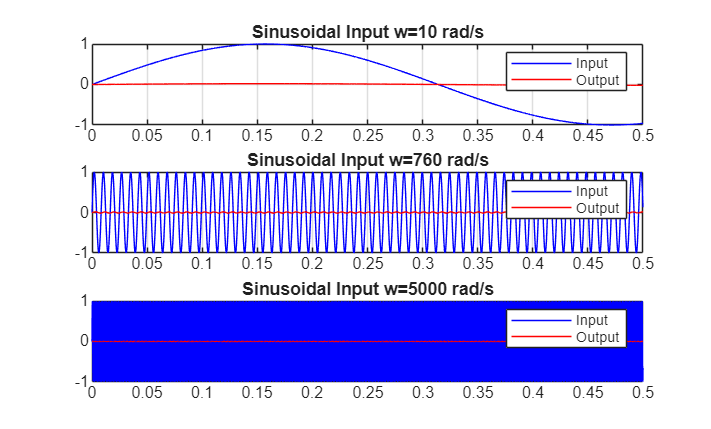


% --- Sinusoidal Input Test ---
t = 0:0.0001:0.5;

% Test multiple frequencies
w1 = 10;    % low frequency
w2 = 760;   % near natural frequency  
w3 = 5000;  % high frequency

u1 = sin(w1*t);
u2 = sin(w2*t);
u3 = sin(w3*t);

% Simulate responses
y1 = lsim(sys_speed, u1, t);
y2 = lsim(sys_speed, u2, t);
y3 = lsim(sys_speed, u3, t);

figure;
subplot(3,1,1);
plot(t, u1, 'b', t, y1, 'r');
title('Sinusoidal Input w=10 rad/s');
legend('Input','Output'); grid on;

subplot(3,1,2);
plot(t, u2, 'b', t, y2, 'r');
title('Sinusoidal Input w=760 rad/s');
legend('Input','Output'); grid on;

subplot(3,1,3);
plot(t, u3, 'b', t, y3, 'r');
title('Sinusoidal Input w=5000 rad/s');
legend('Input','Output'); grid on;


% --- Approximated Model ---
% Your system has a zero at s=-400, close to poles
% Try approximating as simple 2nd order without zero
num_approx = 12 * 400;          % DC gain preserved
den_approx = [1, 760, 240000];
sys_approx = tf(num_approx, den_approx);

disp('Approximated Model:');

Approximated Model:


sys_approx


sys_approx =
 
          4800
  --------------------
  s^2 + 760 s + 240000
 
Continuous-time transfer function.


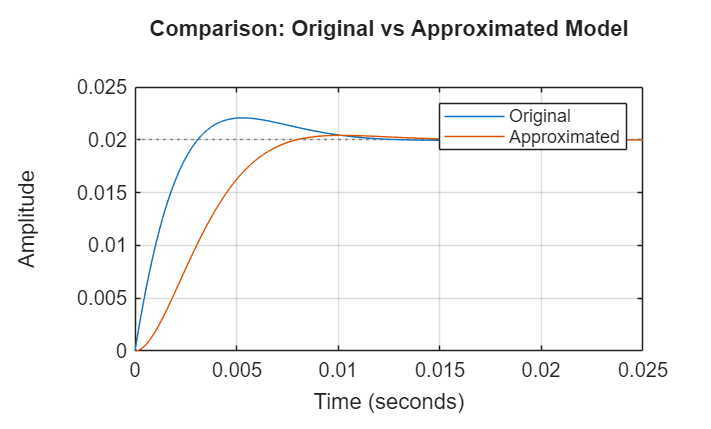


% --- Compare original vs approximated ---
figure;
step(sys_speed, sys_approx);
legend('Original', 'Approximated');
title('Comparison: Original vs Approximated Model');
grid on;

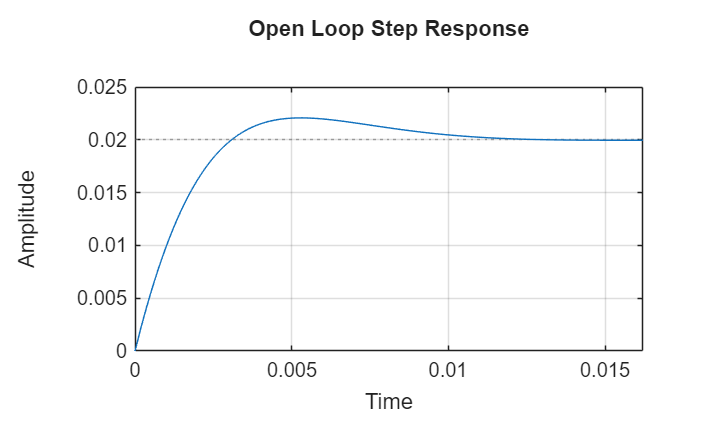

figure('Color','w');
step(sys_speed);
title('Open Loop Step Response');
grid on;

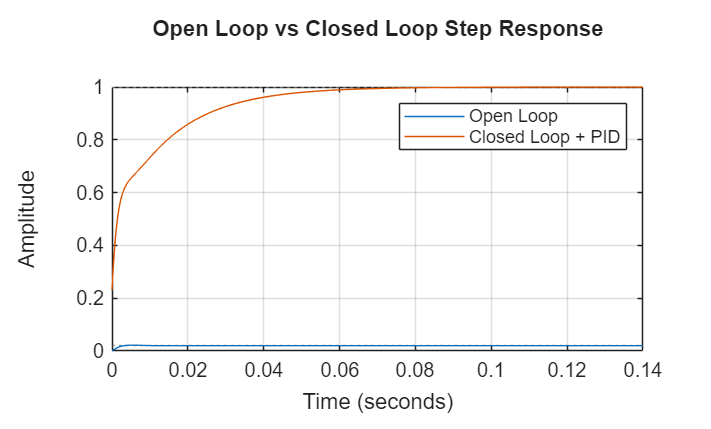

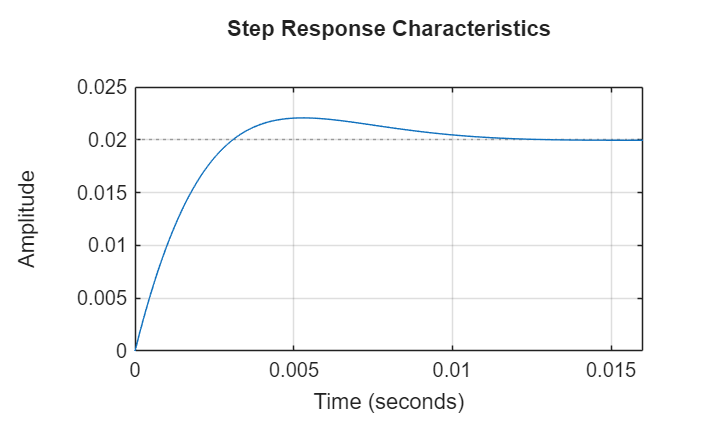

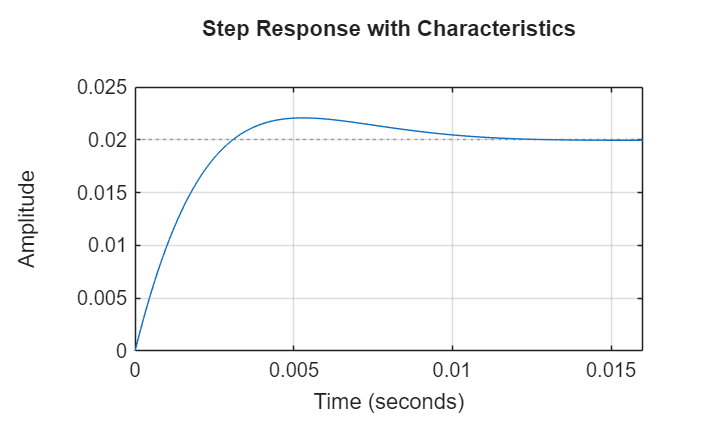

ans = struct with fields:
         RiseTime: 0.0022
    TransientTime: 0.0102
     SettlingTime: 0.0102
      SettlingMin: 0.0180
      SettlingMax: 0.0221
        Overshoot: 10.3774
       Undershoot: 0
             Peak: 0.0221
         PeakTime: 0.0053



figure('Color','w');
step(sys_speed, sys_cl_pid);
legend('Open Loop','Closed Loop + PID');
title('Open Loop vs Closed Loop Step Response');
grid on;

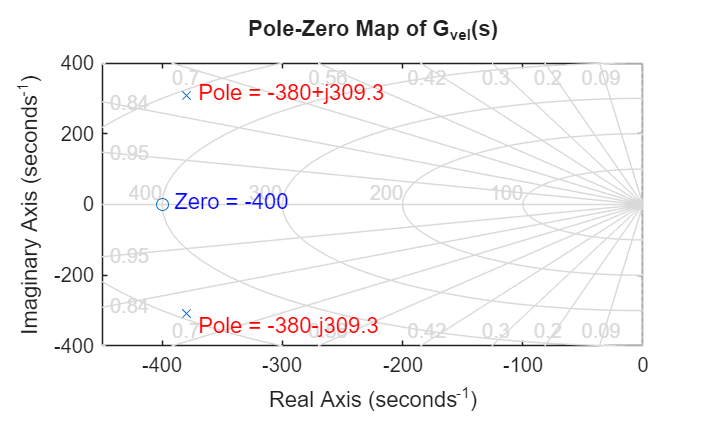

%% Pole-Zero Map
figure('Color','w');

% Plot pole-zero map
pzmap(sys_speed);

% Customize
title('Pole-Zero Map of G_{vel}(s)');
xlabel('Real Axis');
ylabel('Imaginary Axis');
grid on;
sgrid; % adds damping ratio and natural frequency lines

% Add labels on poles and zeros
hold on;
% Zero at s = -400
text(-400, 10, '  Zero = -400', 'Color', 'b', 'FontSize', 11);
% Poles at s = -380 ± j309.3
text(-380, 309.3+10,  '  Pole = -380+j309.3', 'Color', 'r', 'FontSize', 11);
text(-380, -309.3-30, '  Pole = -380-j309.3', 'Color', 'r', 'FontSize', 11);